# Honours Live Script 6

## Load Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

## Save Data

if exist("workspaceVarHonours", 'var')
    clearVarsArray = clearVars();
    clear(clearVarsArray{:})
    clear clearVarsArray
    save matlabHonours.mat
end

% set the default intepreter to latex
setInterpLatex()

## Contents

Effect of Stochasticity Simulations - Problem Setup 1

Connectivity Variation Analysis

Autocorrelation for Coral Trout Connectivity - Monthly

Autocorrelation for Coral Trout Connectivity - Yearly

Autocorrelation for COTS Connectivity - Weekly

Premilinary Experiment Decision Heatmaps - South GBR

Investigating How Decisions Change Code

## Assumptions Made

% when investigating the effects of connectivity, I'm just taking the reefs
% with the highest average connection strengths to start with, and then
% adding a third based in then highest average between the other two - it's
% a pretty hacky method

% for the investigation of stochasticity stuff, I'm giving them all uniform
% areas of 1

% when looking at the stochasticity I'm just going to take the maens and
% variances of the size weighted sum of abundances

## Effect of Stochasticity Simulations - Problem Setup 1

% so, we want to look into the effects of stochasticity using a two-reef
% system

% I guess a simple enough method could be to use pairs of reefs which have
% already high connectivity - fuck it actually, I'm going to use three
% reefs instead

% the cool thing is though, that I can just deliberately look for pairs of
% reefs with already high connectivity, and just choose that way methinks,
% and then purposely inflate the values

% let's first calculate the average connectivity strengths across all of
% the reefs
aveConMatCT = zeros(nReefsCT, nReefsCT);
for m = 1:nMatsCT
    aveConMatCT = aveConMatCT + conMatsCT{m};
end
aveConMatCT = aveConMatCT / nMatsCT;

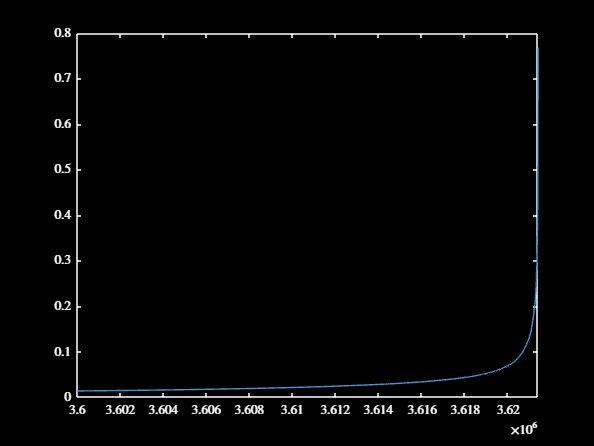

% plot the results just because I'm annoying
figure
plot(sort(aveConMatCT(:)))
xlim([3.6 * 10^6, nReefsCT^2])
darkFig()

% alright, let's now just find the highest pair
[var1, var2] = max(aveConMatCT - diag(diag(aveConMatCT)), [], ...
    "all")

var1 = 0.5684

var2 = 2576098

[r1CTS, r2CTS] = find(aveConMatCT == var1)

r1CTS = 1339

r2CTS = 1354

aveConMatCT(r1CTS, r2CTS)

ans = 0.5684


% now, find the third reef that also gets a high average connectivity from
% the first two
var3 = aveConMatCT - diag(diag(aveConMatCT));
var4 = max(var3(r1CTS, [1:(r2CTS-1), (r2CTS+1):end]), [], "all")

var4 = 0.0538

var5 = max(var3(r2CTS, [1:(r1CTS-1), (r1CTS+1):end]), [], "all")

var5 = 0.0812

[~, r3CTS] = find(aveConMatCT == var5)

r3CTS = 1362


% let's have a look at their average connectivities
ind = [r1CTS, r2CTS, r3CTS];
conMatCTStoch = aveConMatCT(ind, ind)

conMatCTStoch =     0.1038    0.5684    0.0338
    0.0331    0.5710    0.0812
    0.0087    0.1187    0.1442



% this is somewhat a hacky method for selecting those reefs, but whatever
% she'll be right for now

% we need to now form the collection of connectivity matrices
conMatsCTStoch = cell(1, nMatsCT);
for i = 1:nMatsCT
    conMatsCTStoch{i} = full(conMatsCT{i}(ind, ind));
end

conMatsCTStoch{2}

ans =     0.1920    0.6976    0.0056
    0.0687    0.8539    0.0203
    0.0022    0.4437    0.1677


% idea - simulating their abundances over the normal connectivity matrices
% for say 20 years with a 20 year warmup period can get us to a baseline
% level of stochasticity

% we can then add in the demographic and recruitment stochasticity,
% independently and in pairs

% realistically, we could maybe do a fun little imagesc thingo for a grid
% between these two
sizeVecCT = sizeVec;

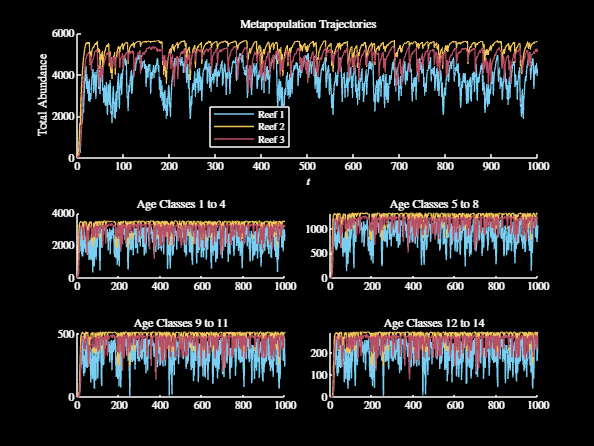

% to calibrate the initial population, let's run the smaller model for 1000
% years and take the average of the last 100
rng(1)
areaVecCTStoch = [1, 1, 1];
var1 = 0.5 * ones(3, 14);
var2 = 1000;
randStruct = struct();
randStruct.randType = "randSelection";
rantStruct.sequence = randi(nMatsCT, [1, var2]);
popMat = baseMetapopModel(conMatsCTStoch, areaVecCTStoch, var1, ...
        var2, specStructCT, randStruct);
popInitCTStoch = squeeze(mean(popMat(:, :, ceil(0.9 * var2):var2), 3));

% plot the results, to make sure that they look decent
figure
plotMetapop(popMat, 1:var2); 
darkFig()

% ok so first, we can write the code for a good old simulation with just
% the connectivity-based stochasticity, and in this case we will just set
% uniform areas of one for each reef

% setup the relevant parameters etc
tWarmup = 10;
tObservation = 20;
nReps = 1000;
randStruct = struct();
randStruct.randType = "randSelection";

% we will store the variance for the individual reefs, along with the
% variance across the entire system which will give us an idea about the
% variance of the entire system
varVecCon = zeros(nReps, 4);
meanVecCon = zeros(nReps, 4);

% should at some point consider if holding the correlations between reef
% populations is worth it

% loop over the repetitions
for r = 1:nReps

    % simulate the warmup period
    randStruct.sequence = randi(nMatsCT, [1, tWarmup]);
    popMat = baseMetapopModel(conMatsCTStoch, areaVecCTStoch, ...
        popInitCTStoch, tWarmup, specStructCT, randStruct);

    % simulate the observational period
    randStruct.sequence = randi(nMatsCT, [1, tObservation]);
    popMat = baseMetapopModel(conMatsCTStoch, areaVecCTStoch, ...
        squeeze(popMat(:, :, end)), tObservation, specStructCT, ...
        randStruct);

    % convert the raw population outputs to size weighted sums of
    % abundances
    popMat = convertAgeClasses(popMat, sizeVecCT);

    % calculate the means and variances at each of the reefs and system
    varVecCon(r, 1:3) = var(popMat, 0, 2)';
    meanVecCon(r, 1:3) = mean(popMat, 2)';
    popMatSys = sum(popMat, 1);
    varVecCon(r, 4) = var(popMatSys, 0, 2);
    meanVecCon(r, 4) = mean(popMatSys, 2);

end
clear popMat randStruct popMatSys

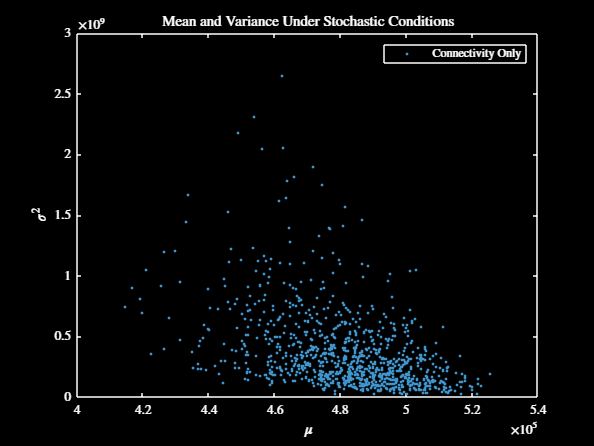

% because I'm bored and want to make a pretty picture, let's plot the
% results of the above
figure
hold on
plot(meanVecCon(:, 1), varVecCon(:, 1), '.')
plot(meanVecCon(:, 2), varVecCon(:, 2), '.')
plot(meanVecCon(:, 3), varVecCon(:, 3), '.')
plot(meanVecCon(:, 4), varVecCon(:, 4), '.')
xlabel("$\mu$")
ylabel("$\sigma^2$")
title("Mean and Variance Under Stochastic Conditions")
subtitle("Connectivity Stochasticity Only")
legend("Connectivity Only")
darkFig()

## Connectivity Variation Analysis

% before proceeding any further, it makes sense to start thinking about
% quantifying the stochasticity surrounding this larval transfer
size(conMatsCT{1})

ans =         1903        1903


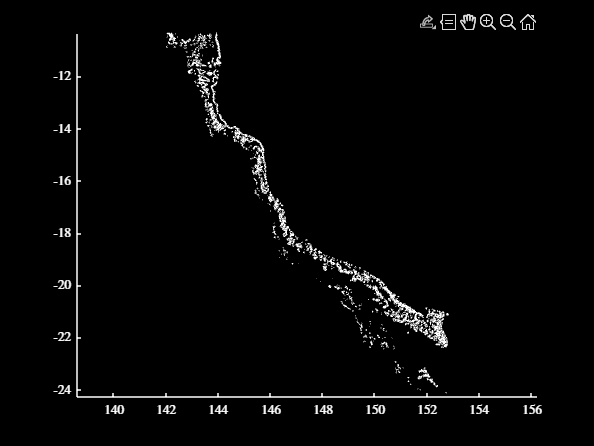

% plot the shape file of all the reefs we have
figure
plotShapeStruct(GBRShapeCT)
darkFig()

% create some interesting statistics
totalConnCT = length(conMatsCT{1})^2

totalConnCT = 3621409

var1 = zeros(nReefsCT, nReefsCT);
for i = 1:nMatsCT
    var1 = var1 + conMatsCT{i};
end
zeroConnCT = sum(var1 == 0, "all")

zeroConnCT = 2993934

nonzeroConnCT = sum(var1 > 0, "all")

nonzeroConnCT = 627475

nonzeroConnCT + zeroConnCT == totalConnCT

ans = logical
   1


% for now, let's determine the connections which have at least one nonzero
% value
[meanConnCT, stdConnCT, minMaxConnCT, ~] = connectivityAnalysis( ...
    conMatsCT, eps);

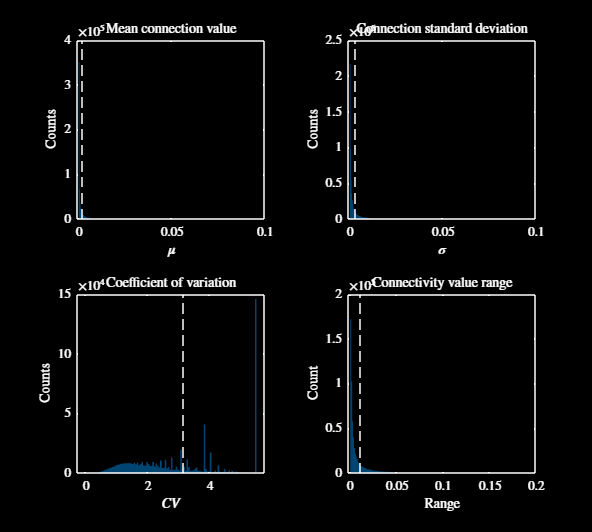

% let's plot the results
plotConnectivityAnalysis(meanConnCT, stdConnCT, minMaxConnCT, eps, ...
    "Coral Trout Monthly", {[-0.001, 0.1], [-0.001, 0.1], [], ...
    [-0.0025, 0.2]})
saveFig("connectivityAnalysisCoralTrout")

% repeat the same analysis for the SLIM model outputs for COTS
[meanConnSLIM, stdConnSLIM, minMaxConnSLIM, ~] = ...
    connectivityAnalysis(conMatsSLIM, eps);

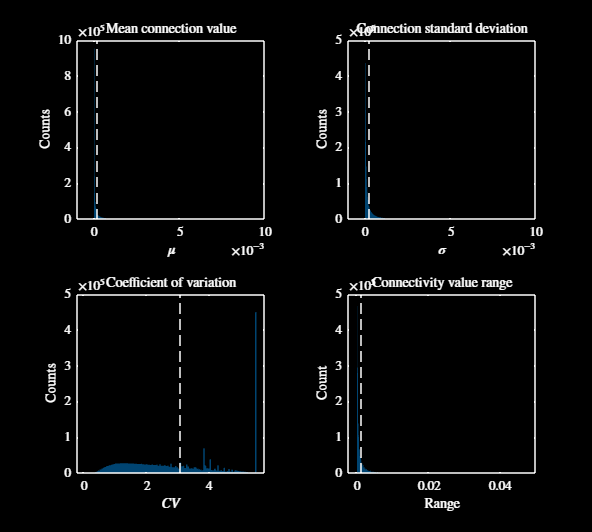

% let's plot the results
plotConnectivityAnalysis(meanConnSLIM, stdConnSLIM, minMaxConnSLIM, ...
    eps, "COTS (SLIM) Weekly", {[-0.001, 0.01], [-0.001, 0.01], [], ...
    [-0.0025, 0.05]})
saveFig("connectivityAnalysisSLIM")

% repeat the same analysis for the GBRLUp model outputs for COTS
[meanConnGBRLUp, stdConnGBRLUp, minMaxConnGBRLUp, ~] = ...
    connectivityAnalysis(conMatsGBRLUp, eps);

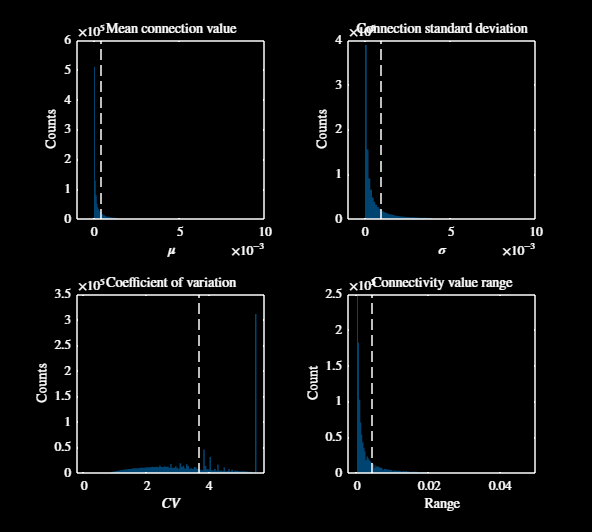

% let's plot the results
plotConnectivityAnalysis(meanConnGBRLUp, stdConnGBRLUp, minMaxConnGBRLUp, ...
    eps, "COTS (GBRLUp) Weekly", {[-0.001, 0.01], [-0.001, 0.01], [], ...
    [-0.0025, 0.05]})
saveFig("connectivityAnalysisGBRLUp")

% repeat the same analysis for the GBRLMd model outputs for COTS
[meanConnGBRLMd, stdConnGBRLMd, minMaxConnGBRLMd, ~] = connectivityAnalysis( ...
    conMatsGBRLMd, eps);

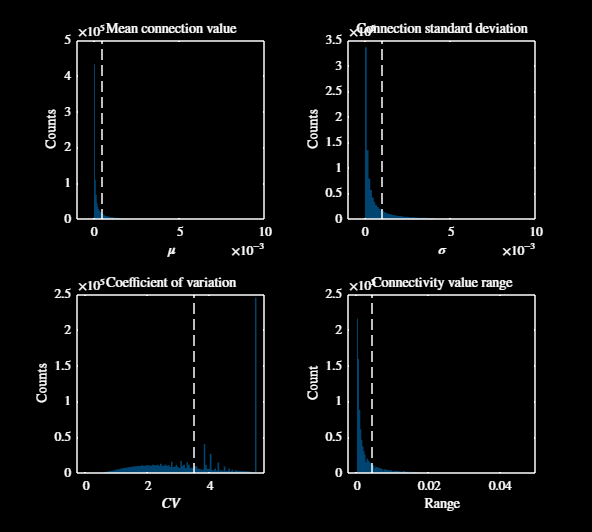

% let's plot the results
plotConnectivityAnalysis(meanConnGBRLMd, stdConnGBRLMd, minMaxConnGBRLMd, ...
    eps, "COTS (GBRLMd) Weekly", {[-0.001, 0.01], [-0.001, 0.01], [], ...
    [-0.0025, 0.05]})
saveFig("connectivityAnalysisGBRLMd")

% repeat the same analysis for the GBRLMd model outputs for COTS
[meanConnGBRLDp, stdConnGBRLDp, minMaxConnGBRLDp, ~] = connectivityAnalysis( ...
    conMatsGBRLDp, eps);

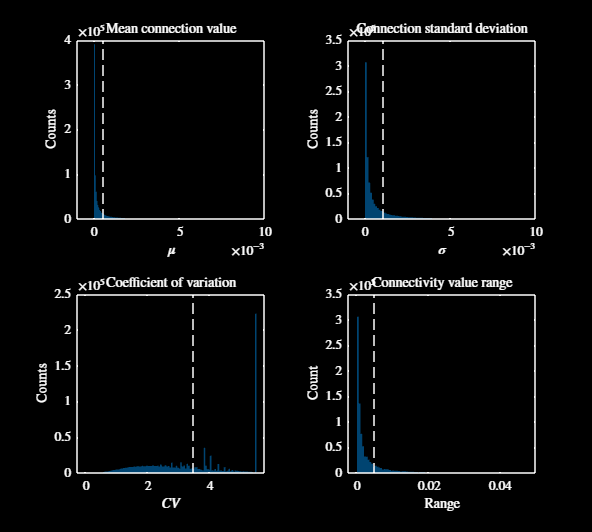

% let's plot the results
plotConnectivityAnalysis(meanConnGBRLDp, stdConnGBRLDp, minMaxConnGBRLDp, ...
    eps, "COTS (GBRLDp) Weekly", {[-0.001, 0.01], [-0.001, 0.01], [], ...
    [-0.0025, 0.05]})
saveFig("connectivityAnalysisGBRLDp")

% let's also plot the number of years with nonzero connections, just for
% the connections that exist in at least one year
thresh1 = 1 / nMatsCT;
var1 = zeros(nReefsCT, nReefsCT);
for i = 1:nMatsCT
    var1 = var1 + (conMatsCT{i} > 0);
end
var2 = sum(var1 > 0, "all")

var2 = 627475


% let's go ahead and plot the number of nonzero years each connection with
% at least one nonzero years has

% let's find the median values for some of these, which could help us

% define the average reef

## Autocorrelation for Coral Trout Connectivity - Monthly

% need to first re-familiarise myself with what the time scales are for
% these matrices
% for i = 1:length(conMatsCTNames)
%     conMatsCTNames(i)
% end

% well shit, pretty clearly not all of the points are spaced equally, so
% our analysis will need to take this into account - we can look at this on
% two scales - month-to-month autocorrelation, and year-to-year averaged
% autocorrelation

% for now, let's just look at this for each connection, however it may be
% useful to think about considering connections which have at least one
% nonzero value, as the connections which are 0 each time will skew results

% let's calculate all of these autocorrelations for the suitable
% connections
ind = [1:5, 7:11, 13:17, 19:23, 25:29];
tic
[autocorrMonthlyCT, autocorrRankMonthlyCT, ~] = calcAutocorr( ...
    conMatsCT, eps, ind);
toc

Elapsed time is 101.697683 seconds.


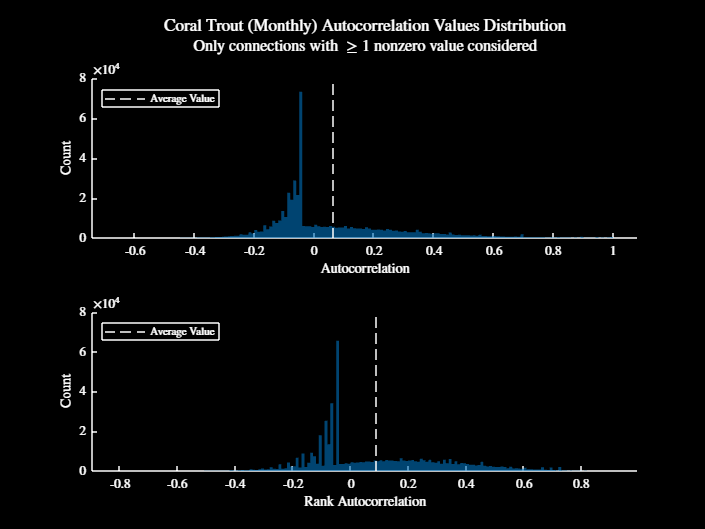

% clearly, that is a pretty low value, especially when noting that we are
% considering any connection with at least one nonzero value

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrMonthlyCT, autocorrRankMonthlyCT, eps, "Coral " + ...
    "Trout (Monthly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisCoralTroutMonthly")

% this is pretty strange

% let's repeat the analysis, but only for connections which have at least
% 50% nonzero connections across the time series
ind = [1:5, 7:11, 13:17, 19:23, 25:29];
tic
[autocorrMonthly50CT, autocorrRankMonthly50CT, ~] = calcAutocorr(conMatsCT, ...
    0.5, ind);
toc

Elapsed time is 63.868383 seconds.


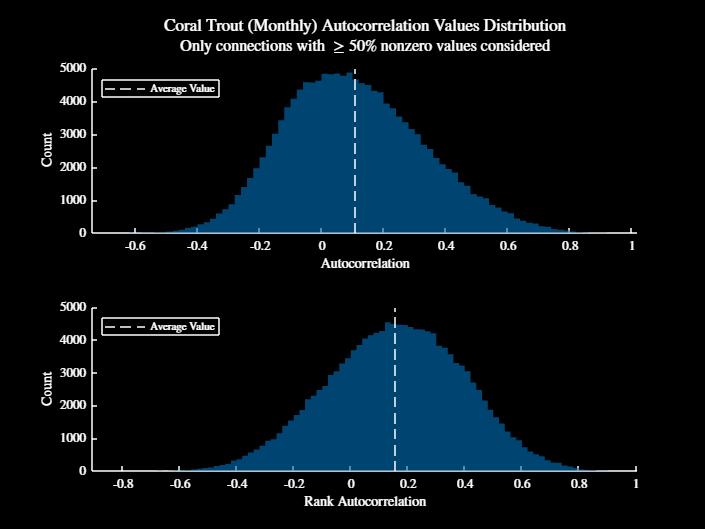

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrMonthly50CT, autocorrRankMonthly50CT, 0.5, ...
    "Coral Trout (Monthly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisCoralTroutMonthly50p")

% let's repeat the 50% analysis thingy, but this time take random
% permutations of the connectivity values 10 times, and store the average
% autocorrelation
ind = [1:5, 7:11, 13:17, 19:23, 25:29];
tic
[autocorrMonthly50CTRand, autocorrRankMonthly50CTRand, ~] = calcAutocorr( ...
    conMatsCT, 0.5, ind, "rand");
toc

Elapsed time is 326.728723 seconds.


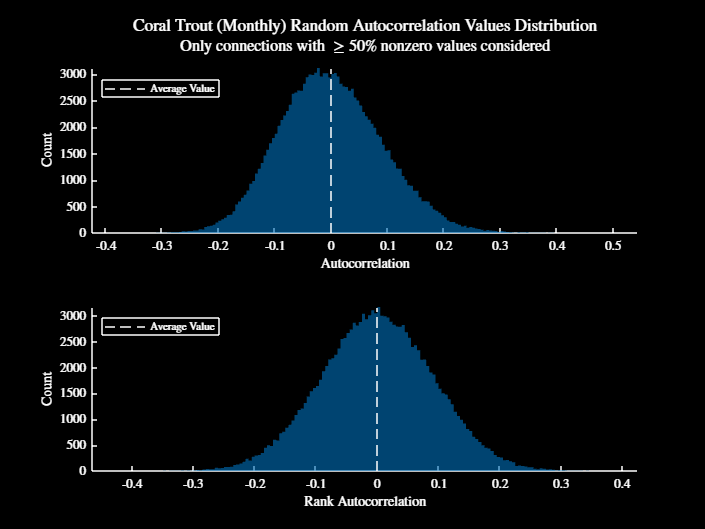

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrMonthly50CTRand, autocorrRankMonthly50CTRand, ...
    0.5, "Coral Trout (Monthly) Random")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisCoralTroutMonthly50pRand")

sum(abs(autocorrMonthly50CTRand - autocorrMonthly50CT))

ans = 4.3840e-12

## Autocorrelation for Coral Trout Connectivity - Yearly

% need to create a cell array for the yearly matrices now
conMatsCTYearly = cell(1, 5);
for i = 1:5
    conMatsCTYearly{i} = zeros(nReefsCT, nReefsCT);
    for j = 1:6
        conMatsCTYearly{i} = conMatsCTYearly{i} + conMatsCT{j + 6 * (i-1)};
    end
    conMatsCTYearly{i} = conMatsCTYearly{i} / 6;
end
[autocorrYearly50CT, autocorrRankYearly50CT, ~] = ...
    calcAutocorr(conMatsCTYearly, 0.5);

% let's also plot the distibution of these autocorrelation values
% plotAutocorrVals(autocorrYearly50CT, autocorrRankYearly50CT, eps, "Coral " + ...
%     "Trout (Yearly)")
% darkFig()
% figResize(1.5, 1.5)
% saveFig("autocorrelationAnalysisCoralTroutMonthly")

% hmmm - there is better autocorrelation from year-to-year than from
% month-to-month, but is this really significant, or just a result of the
% averaging

% idea that I should look at later - for the month-to-month comparisons,
% think about looking into autocorrelation of rolling averages maybe, that
% could be an interesting way to go about things

## Autocorrelation for COTS Connectivity - Weekly

% load in the COTS matrices
cd ../../../../'Research Assistant Work (OD)'/'COTS (OD)'/Code/
load matlabCOTS SLIMCell SLIMNames GBRLUpCell GBRLMdCell GBRLDpCell ...
    GBRLUpNames 
GBRLNames = GBRLUpNames;
conMatsSLIM = SLIMCell;
conMatsGBRLUp = GBRLUpCell;
conMatsGBRLMd = GBRLMdCell;
conMatsGBRLDp = GBRLDpCell;
clear GBRLUpNames SLIMCell GBRLUpCell GBRLMdCell GBRLDpCell
cd ../../../'Uni (OD)'/'2023 Sem 2 (OD)'/'MXN404 (OD)'/Code/

% now let's repeat the same analyses for these matrices lmao
sum(SLIMNames == GBRLNames)

ans = 30


% ok, so looks like both sets of matrices have the exact same dates, but
% what are they?
for i = 1:length(SLIMNames)
    % SLIMNames(i)
end

% so we have patterns of 10 weeks of spawning, over 3 total spawning
% seasons - let's do the weekly analyses on these matrices
ind = [1:9, 10:19, 20:29];
tic
[autocorrWeeklySLIM, autocorrRankWeeklySLIM, ~] = calcAutocorr( ...
    conMatsSLIM, eps, ind);
toc

Elapsed time is 976.416829 seconds.


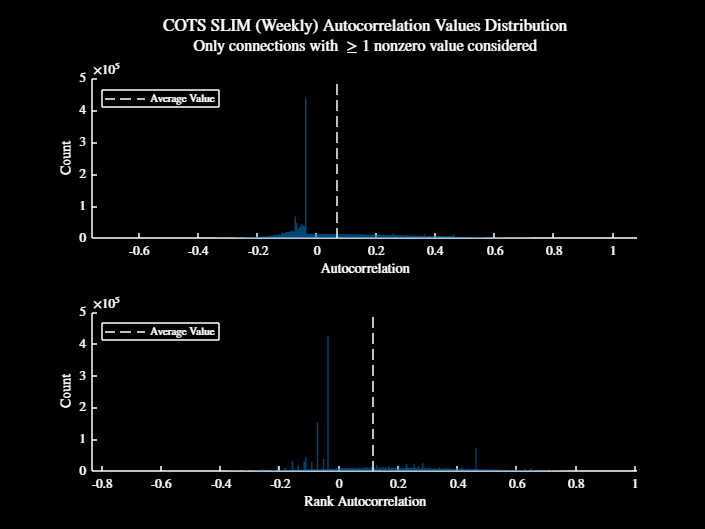

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrWeeklySLIM, autocorrRankWeeklySLIM, eps, ...
    "COTS SLIM (Weekly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisSLIMWeekly")


% this is pretty strange

% do it again, but for the connections with at least 50% nonzero values
ind = [1:9, 10:19, 20:29];
tic
[autocorrWeeklySLIM50, autocorrRankWeeklySLIM50, ~] = calcAutocorr( ...
    conMatsSLIM, 0.5, ind);
toc

Elapsed time is 265.948190 seconds.


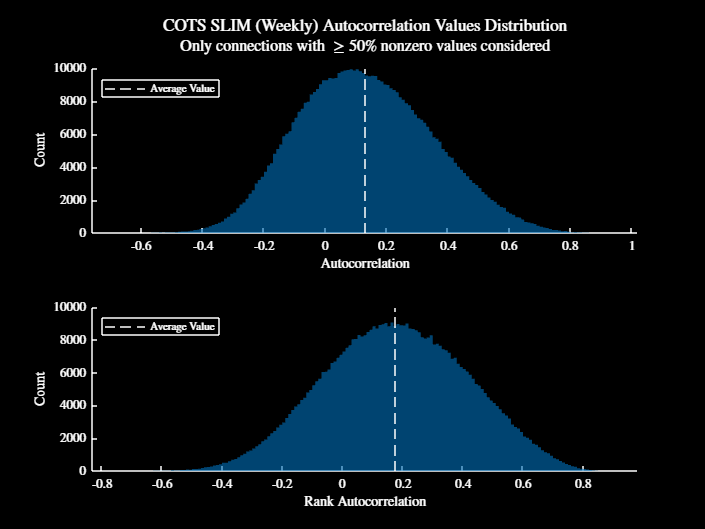

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrWeeklySLIM50, autocorrRankWeeklySLIM50, 0.5, ...
    "COTS SLIM (Weekly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisSLIMWeekly50p")


% this is pretty strange

% do the same for GBRLUp
ind = [1:9, 10:19, 20:29];
tic
[autocorrWeeklyGBRLUp, autocorrRankWeeklyGBRLUp, ~] = calcAutocorr( ...
    conMatsGBRLUp, eps, ind);
toc

Elapsed time is 514.261461 seconds.


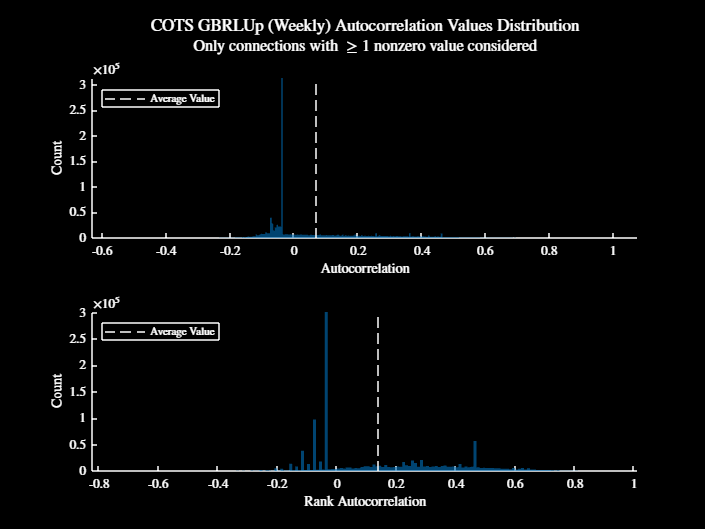

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrWeeklyGBRLUp, autocorrRankWeeklyGBRLUp, eps, ...
    "COTS GBRLUp (Weekly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisGBRLUpWeekly")

% should repeat the above analysis once I have a chance
ind = [1:9, 10:19, 20:29];
tic
[autocorrWeeklyGBRLUp50, autocorrRankWeeklyGBRLUp50, ~] = calcAutocorr( ...
    conMatsGBRLUp, 0.5, ind);
toc

Elapsed time is 61.169998 seconds.


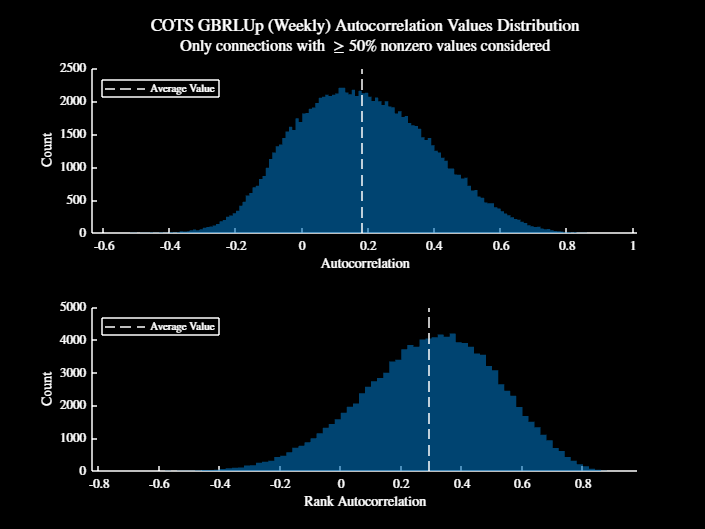

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrWeeklyGBRLUp50, autocorrRankWeeklyGBRLUp50, 0.5, ...
    "COTS GBRLUp (Weekly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisGBRLUpWeekly50p")

% do the same for GBRLMd
ind = [1:9, 10:19, 20:29];
tic
[autocorrWeeklyGBRLMd, autocorrRankWeeklyGBRLMd, ~] = calcAutocorr( ...
    conMatsGBRLMd, eps, ind);
toc

Elapsed time is 455.630280 seconds.


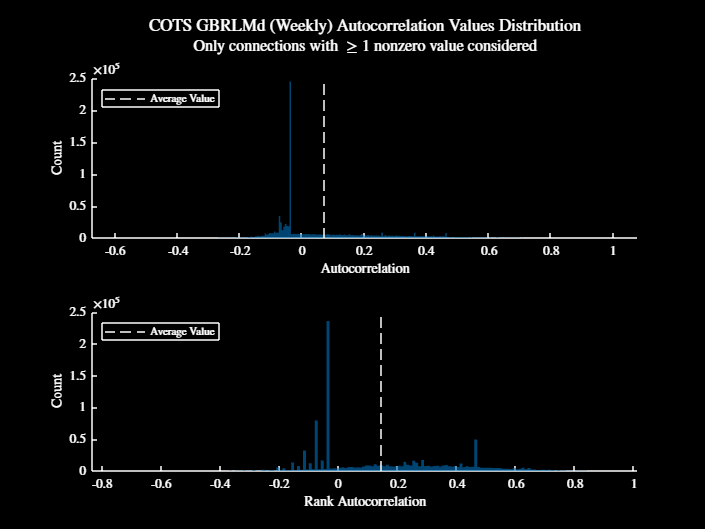

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrWeeklyGBRLMd, autocorrRankWeeklyGBRLMd, eps, ...
    "COTS GBRLMd (Weekly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisGBRLMdWeekly")

% repeat, but for 50% nonzero connections only
ind = [1:9, 10:19, 20:29];
tic
[autocorrWeeklyGBRLMd50, autocorrRankWeeklyGBRLMd50, ~] = calcAutocorr( ...
    conMatsGBRLMd, 0.5, ind);
toc

Elapsed time is 75.181311 seconds.


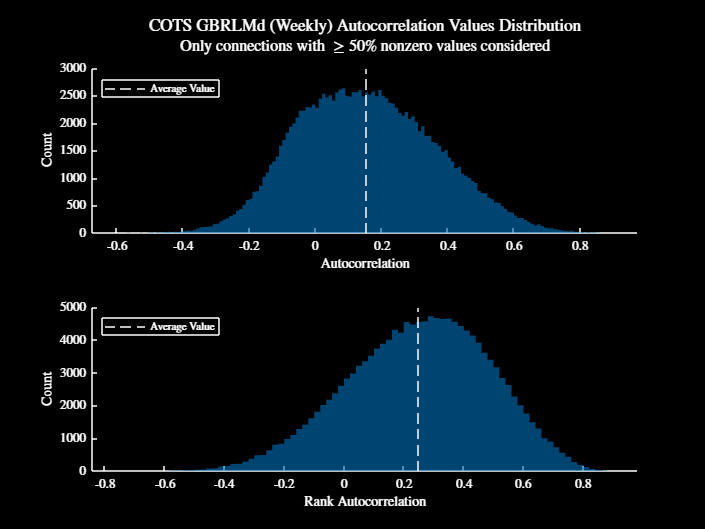

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrWeeklyGBRLMd50, autocorrRankWeeklyGBRLMd50, 0.5, ...
    "COTS GBRLMd (Weekly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisGBRLMdWeekly50p")

% do the same for GBRLDp
ind = [1:9, 10:19, 20:29];
tic
[autocorrWeeklyGBRLDp, autocorrRankWeeklyGBRLDp, ~] = calcAutocorr( ...
    conMatsGBRLDp, eps, ind);
toc

Elapsed time is 411.475298 seconds.


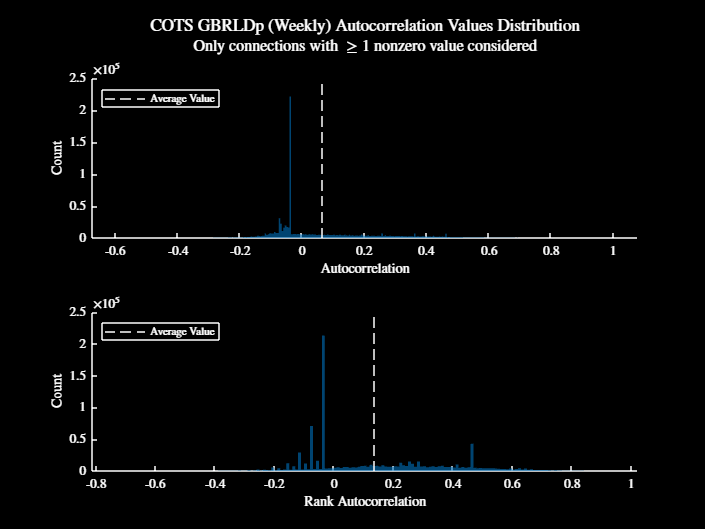

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrWeeklyGBRLDp, autocorrRankWeeklyGBRLDp, eps, ...
    "COTS GBRLDp (Weekly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisGBRLDpWeekly")

% repeat, but for 50% nonzero connections only
ind = [1:9, 10:19, 20:29];
tic
[autocorrWeeklyGBRLDp50, autocorrRankWeeklyGBRLDp50, ~] = calcAutocorr( ...
    conMatsGBRLDp, 0.5, ind);
toc

Elapsed time is 76.649642 seconds.


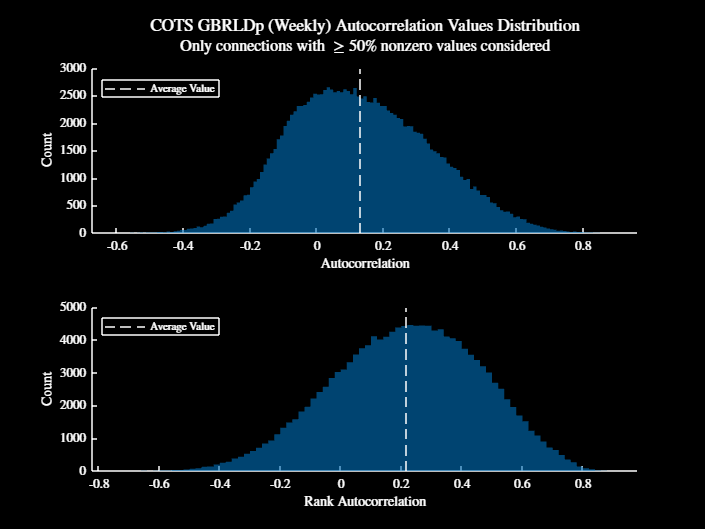

% let's also plot the distibution of these autocorrelation values
plotAutocorrVals(autocorrWeeklyGBRLDp50, autocorrRankWeeklyGBRLDp50, 0.5, ...
    "COTS GBRLDp (Weekly)")
darkFig()
figResize(1.5, 1.5)
saveFig("autocorrelationAnalysisGBRLDpWeekly50p")

## Premilinary Experiment Decision Heatmaps - South GBR

% plot a heatmap of the decisions which have been made for the south of the
% GBR
modStrings = ["$k = 1$", "$k = 0.75$", "$k = 0.5$", "$k = 0.25$", ...
    "$k = 0$"];
figure
figResize(2.5, 1.25)
plotSelectionHeatmap(mpaSelCTSouth, 1:5, modStrings, "Coral Trout (South GBR)", ...
    GBRShapeCTSouth)
saveFig("heatmapMPTCTSouth")

% now, plot the frequency of the selections
figure
figResize(2.5, 1.25)
plotSelectionHeatmap(mpaSelCTSouth, 1:5, modStrings,  "Coral Trout (South GBR)", ...
    GBRShapeCTSouth, "frequency")
saveFig("frequencyMPTCTSouth")

## Premilinary Experiment Decision Heatmaps - Swains

% plot a heatmap of the decisions which have been made for the south of the
% GBR
modStrings = ["$k = 1$", "$k = 0.75$", "$k = 0.5$", "$k = 0.25$", ...
    "$k = 0$"];
figure
figResize(2.5, 1.25)
plotSelectionHeatmap(mpaSelCTSwains, 1:5, modStrings, "Coral Trout (Swains)", ...
    GBRShapeCTSwains)
saveFig("heatmapMPTCTSwains")

% now, plot the frequency of the selections
figure
figResize(2.5, 1.25)
plotSelectionHeatmap(mpaSelCTSwains, 1:5, modStrings, "Coral Trout (Swains)", ...
    GBRShapeCTSwains, "frequency")
saveFig("frequencyMPTCTSwains")

## Premilinary Experiment Decision Heatmaps - Townsville

% plot a heatmap of the decisions which have been made for the south of the
% GBR
modStrings = ["$k = 1$", "$k = 0.75$", "$k = 0.5$", "$k = 0.25$", ...
    "$k = 0$"];
figure
figResize(2.5, 1.25)
plotSelectionHeatmap(mpaSelCTTowns, 1:5, modStrings, "Coral Trout (Townsville)", ...
    GBRShapeCTTowns)
saveFig("heatmapMPTCTTowns")

% now, plot the frequency of the selections
figure
figResize(2.5, 1.25)
plotSelectionHeatmap(mpaSelCTTowns, 1:5, modStrings, "Coral Trout (Townsville)", ...
    GBRShapeCTTowns, "frequency")
saveFig("frequencyMPTCTTowns")

## Investigating How Decisions Change Code

% we're gonna wanna do a number of things for this, but I'm going to start
% with the overlaps between MPA networks
var1 = calcOverlapProps(mpaSelCTSouth, 1:5);
var2 = mean(var1, 3);

% write the code which will plot them
figure
imagesc(var2)
colormap(myColourMap())
colorbar()
xticks(1:5)
yticks(1:5)
xticklabels(modStrings)
yticklabels(modStrings)
darkFig()

% look at the number of reefs chosen by each model methinks
var3 = calcNumReefsChosen(mpaSelCTSouth);
mean(var3, 1)

% write the code which will plot the results
maxVal = max(max(var3));
figure
hold on
xBins = linspace(0, maxVal, 10);
for i = 1:5
    [yVals, xVals] = histcounts(var3(:, i), xBins);
    plot((xVals(2:end) + xVals(1:(end-1))) / 2, yVals)
end
xlabel("Number of reefs chosen")
ylabel("Count")
legend(modStrings)
darkFig()
clear xBins maxVal